%% ===== 0) 路徑與參數（自行修改） =====
clc; clear;
MMWAVE_DIR = "D:\deff\0925永康1\f1";              % 內含 replay_*.json
KINECT_CSV = "D:\deff\0925永康1\f1\output.csv";  % output.csv 路徑
POINT_KEY  = "pointCloud";     % 你的點雲欄位名（若不同，改這個就好）
MAX_GAP_MS = 0.08;        % 對齊容許誤差 (ms)
POINT_SIZE = 12;               % 點雲大小
mAX = [-2 2 0 4 -1 2];         % 顯示範圍
% sAX = [-2 2 -2 2 -1 2];         % 顯示範圍
sAX = [-1 1 -1 1 -1 1]*0.5; 
PAUSE_SEC = 1e-6;

% 骨架設定（每點 4 欄：x,y,vis,?；沿用你的索引與連線）
sk_index = [0,11,12,13,14,15,16,23,24,25,26,27,28];
caserh = [1,2,4,6]; caselh = [1,3,5,7]; caserl = [2,8,10,12]; casell = [3,9,11,13];

%% ===== 1) 讀 mmWave：串接 replay_*.json，依「時:分:秒:毫秒」排序 =====
frames = [];
jfs = dir(fullfile(MMWAVE_DIR,"replay_*.json"));
assert(~isempty(jfs),"在 %s 找不到 replay_*.json", MMWAVE_DIR);

% 依檔名 replay_#.json 的 # 排序（沒有 # 就當 0）
nums = zeros(numel(jfs),1);
for i = 1:numel(jfs)
    m = regexp(jfs(i).name,"^replay_(\d+)\.json$","tokens","once");
    if ~isempty(m), nums(i) = str2double(m{1}); end
end
[~,ord] = sort(nums); jfs = jfs(ord);

% 串接 data[]
for i = 1:numel(jfs)
    d = jsondecode(fileread(fullfile(jfs(i).folder,jfs(i).name)));
    if ~isfield(d,'data'), continue; end
    if isstruct(d.data)
        frames = [frames; d.data(:)];
    elseif iscell(d.data)
        frames = [frames; [d.data{:}]'];
    end
end
assert(~isempty(frames),"replay_* 檔案裡沒有 data 幀");
for i = 1:numel(frames)
    ts = string(frames(i).timestamp);               % 'YYYY/MM/DD HH:MM:SS.mmm'
    dt = datetime(ts,'InputFormat','yyyy/MM/dd HH:mm:ss.SSS');
    hh(i,1) = hour(dt);
    mm(i,1) = minute(dt);
    ss(i,1) = second(dt);
    mm_ts_ms(i,1) = hh(i,1)*3600 + mm(i,1)*60 + ss(i,1);
end
[mm_ts_ms, ord] = sort(mm_ts_ms);
frames = frames(ord);

%% ===== 2) 讀 Kinect：output.csv → 抽骨架座標（不改 label）=====
kinect = table2array(readtable(KINECT_CSV));  % [N x (4 + 4*J)]
sktime  = kinect(:,1:4);                      % [hh mm ss ms]
skdata  = kinect(:,5:end);

H=sktime(:,1); 
M=sktime(:,2); 
S=sktime(:,3); 
MS=sktime(:,4);
sk_ts_ms = H*3600 + M*60 + S + MS*0.001;

select_skdata = cell(size(skdata,1),1);
for i=1:size(skdata,1)
    row = skdata(i,:);
    tmp = zeros(numel(sk_index),3);
    for k=1:numel(sk_index)
        j = sk_index(k);
        tmp(k,1) = row(4*j+1) - 0.5; % x
        tmp(k,2) = row(4*j+2) - 0.5; % y
        tmp(k,3) = row(4*j+3);       % z/vis
    end
    select_skdata{i} = tmp;
end
%% 對齊：以 mmWave 為主
N = numel(mm_ts_ms);
aligned = nan(N,5);   % [mm_idx, sk_idx, mm_time, sk_time, diff_ms]

for i = 1:N
    % 找最近的 Kinect 幀
    [gap, j] = min(abs(sk_ts_ms - mm_ts_ms(i)));

    aligned(i,1) = i;                % mm 幀 index
    aligned(i,2) = j;                % 對應的 skeleton 幀 index
    aligned(i,3) = hh(i); % hh 幀時間
    aligned(i,4) = mm(i); % mm 幀時間
    aligned(i,5) = ss(i); % ss 幀時間
    aligned(i,6) =  mm_ts_ms(i) - sk_ts_ms(j); % 時間差 (ms)，可正可負
end

%% ===== 3) 畫在一起：逐幀最近時間對齊 → 點雲 + 骨架 =====
MAX_GAP_S = MAX_GAP_MS;               % 你用 0.08 秒 (= 80 ms)
tiledlayout(2,1,'TileSpacing','compact','Padding','compact');

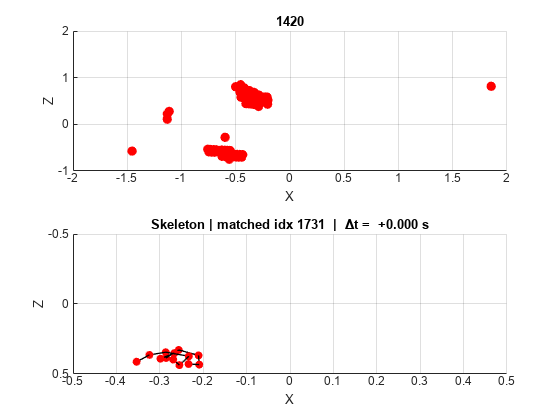

f = figure('Color','w');

for i = 1:N
    % 取 mmWave 點雲
    PC = [];
    F = frames(i);
    if isfield(F,'frameData'), F = F.frameData; end
    if isfield(F, POINT_KEY)
        A = F.(POINT_KEY);
        if isnumeric(A)
            PC = A;
        elseif isstruct(A) && all(isfield(A,{'x','y','z'}))
            PC = [[A.x].',[A.y].',[A.z].'];
        elseif iscell(A)
            PC = cell2mat(cellfun(@(x) x(:).', A, 'UniformOutput', false));
        end
        if ~isempty(PC) && size(PC,2) >= 3
            PC = PC(:,1:3);
        else
            PC = [];
        end
    end

    nexttile(1);
    cla;
    if ~isempty(PC)
        scatter3(PC(:,1), PC(:,2), PC(:,3), 50, 'r', 'filled');  % (x, y, z)
    end
    axis(mAX); grid on; xlabel('X'); ylabel('Y'); zlabel('Z');
    set(gca, 'ZDir', 'reverse');   % 反轉 Z 方向
    view(0, 180);
    title(i)
    nexttile(2);
    cla;
    j = aligned(i,2);
    if ~isnan(j) && abs(aligned(i,6)) <= MAX_GAP_S
        aa = select_skdata{j};
        t = aa(caserh,:); plot3(t(:,1)',t(:,3)',t(:,2)','-o','Color','k','MarkerSize',5,'MarkerFaceColor','r','LineWidth',1,'MarkerEdgeColor','r'); hold on;
        t = aa(caselh,:); plot3(t(:,1)',t(:,3)',t(:,2)','-o','Color','k','MarkerSize',5,'MarkerFaceColor','r','LineWidth',1,'MarkerEdgeColor','r');
        t = aa(caserl,:); plot3(t(:,1)',t(:,3)',t(:,2)','-o','Color','k','MarkerSize',5,'MarkerFaceColor','r','LineWidth',1,'MarkerEdgeColor','r');
        t = aa(casell,:); plot3(t(:,1)',t(:,3)',t(:,2)','-o','Color','k','MarkerSize',5,'MarkerFaceColor','r','LineWidth',1,'MarkerEdgeColor','r');
        axis(sAX); grid on; xlabel('X'); ylabel('Y'); zlabel('Z'); view(0,-180);
        title(sprintf('Skeleton | matched idx %d  |  Δt = %+7.3f s', j, aligned(i,6)));
    else
        % 沒有合格配對 → 顯示空圖提示
        axis(sAX); grid on; xlabel('X'); ylabel('Y'); zlabel('Z'); view(0,-180);
        title(sprintf('Skeleton | no match (|Δt| > %.3fs)', MAX_GAP_S));
    end

    drawnow;
    pause(PAUSE_SEC);
end